# Define the spring mass system

m = 1;
k = 1;
b = 1;

A = [0 1;
    -k/m -b/m]

A =      0     1
    -1    -1


B = [0;
     1];
C = [1 0];
D = [0];

## Define model

plant = ss(A, B, C, D)

plant =
 
  A = 
       x1  x2
   x1   0   1
   x2  -1  -1
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



size(plant)

State-space model with 1 outputs, 1 inputs, and 2 states.


plant.InputName = {'f'}

plant =
 
  A = 
       x1  x2
   x1   0   1
   x2  -1  -1
 
  B = 
       f
   x1  0
   x2  1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       f
   y1  0
 
Continuous-time state-space model.



plant.InputUnit = {'N'}

plant =
 
  A = 
       x1  x2
   x1   0   1
   x2  -1  -1
 
  B = 
       f
   x1  0
   x2  1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       f
   y1  0
 
Continuous-time state-space model.



plant.StateName = {'x', 'x_dot'}

plant =
 
  A = 
              x  x_dot
   x          0      1
   x_dot     -1     -1
 
  B = 
          f
   x      0
   x_dot  1
 
  C = 
           x  x_dot
   y1      1      0
 
  D = 
       f
   y1  0
 
Continuous-time state-space model.



plant.StateUnit = {'m', 'm/s'}

plant =
 
  A = 
              x  x_dot
   x          0      1
   x_dot     -1     -1
 
  B = 
          f
   x      0
   x_dot  1
 
  C = 
           x  x_dot
   y1      1      0
 
  D = 
       f
   y1  0
 
Continuous-time state-space model.



plant.OutputName = {'x'}

plant =
 
  A = 
              x  x_dot
   x          0      1
   x_dot     -1     -1
 
  B = 
          f
   x      0
   x_dot  1
 
  C = 
          x  x_dot
   x      1      0
 
  D = 
      f
   x  0
 
Continuous-time state-space model.



plant.OutputUnit = {'m'}

plant =
 
  A = 
              x  x_dot
   x          0      1
   x_dot     -1     -1
 
  B = 
          f
   x      0
   x_dot  1
 
  C = 
          x  x_dot
   x      1      0
 
  D = 
      f
   x  0
 
Continuous-time state-space model.



## Reference signals

dt = 0.01;
t_end = 10;
t_span = 0:dt:t_end;

for i  = 1:length(t_span)
    t = t_span(i);
    r(i) = sin(4*pi*(t/t_end));
end

plant = setmpcsignals(plant, 'MV',1,'MO',1)

plant =
 
  A = 
              x  x_dot
   x          0      1
   x_dot     -1     -1
 
  B = 
          f
   x      0
   x_dot  1
 
  C = 
          x  x_dot
   x      1      0
 
  D = 
      f
   x  0
 
Input groups:              
       Name        Channels
    Manipulated       1    
                           
Output groups:          
      Name      Channels
    Measured       1    
                        
Continuous-time state-space model.



mpcobj = mpc(plant,dt)

-->The "PredictionHorizon" property is empty. Assuming default 10.
-->The "ControlHorizon" property is empty. Assuming default 2.
-->The "Weights.ManipulatedVariables" property is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property is empty. Assuming default 1.00000.
 
MPC object (created on 13-May-2023 17:56:26):
---------------------------------------------
Sampling time:      0.01 (seconds)
Prediction Horizon: 10
Control Horizon:    2

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  2 states  |
                                      |            |-->  1 measured output(s)
      0  measured disturbance(s)   -->|  1 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Dis

xc = mpcstate(mpcobj)

-->Converting model to discrete time.
-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
-->The "Model.Noise" property is empty. Assuming white noise on each measured output.
MPCSTATE object with fields
          Plant: [0 0]
    Disturbance: 0
          Noise: [1×0 double]
       LastMove: 0
     Covariance: [3×3 double]



## Change the initial state

xc.Plant = [0 0]

MPCSTATE object with fields
          Plant: [0 0]
    Disturbance: 0
          Noise: [1×0 double]
       LastMove: 0
     Covariance: [3×3 double]



## Set MPC parameters

mpcobj.ManipulatedVariables.Min = -10;
mpcobj.ManipulatedVariables.Max = 10;
mpcobj.MV.RateMin = -2;
mpcobj.MV.RateMax = 2;
mpcobj.Weights.OutputVariables = 10

 
MPC object (created on 13-May-2023 17:56:26):
---------------------------------------------
Sampling time:      0.01 (seconds)
Prediction Horizon: 10
Control Horizon:    2

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  2 states  |
                                      |            |-->  1 measured output(s)
      0  measured disturbance(s)   -->|  1 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Disturbance and Noise Models:
        Output disturbance model: default (type "getoutdist(mpcobj)" for details)
         Measurement noise model: default (unity gain after scaling)

Weights:
        ManipulatedVariables: 0
    ManipulatedVariablesRate: 0.1000
             OutputVariables: 10
                         ECR: 100000

State Estimation:  Default Kalman Filter (type "ge

mpcobj.Weights.ManipulatedVariables = 0

 
MPC object (created on 13-May-2023 17:56:26):
---------------------------------------------
Sampling time:      0.01 (seconds)
Prediction Horizon: 10
Control Horizon:    2

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  2 states  |
                                      |            |-->  1 measured output(s)
      0  measured disturbance(s)   -->|  1 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Disturbance and Noise Models:
        Output disturbance model: default (type "getoutdist(mpcobj)" for details)
         Measurement noise model: default (unity gain after scaling)

Weights:
        ManipulatedVariables: 0
    ManipulatedVariablesRate: 0.1000
             OutputVariables: 10
                         ECR: 100000

State Estimation:  Default Kalman Filter (type "ge

mpcobj.Weights.ManipulatedVariablesRate = 0;

for i = 1:length(t_span)
    y(i) = C*xc.Plant;
    y_dot(i) = xc.Plant(2);
    u(i) = mpcmove(mpcobj, xc, y(i), r(i));
end

-->Converting model to discrete time.
-->Assuming output disturbance added to measured output channel #1 is integrated white noise.
-->The "Model.Noise" property is empty. Assuming white noise on each measured output.


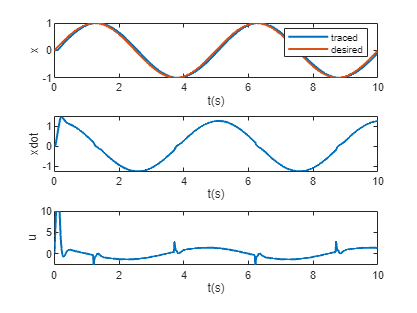

figure()
subplot(3,1,1)
plot(t_span,y,t_span,r, 'lineWidth',1.5)
legend('traced', 'desired')
xlabel('t(s)')
ylabel('x')

subplot(3,1,2)
plot(t_span,y_dot, 'lineWidth',1.5)
xlabel('t(s)')
ylabel('xdot')

subplot(3,1,3)
plot(t_span,u, 'lineWidth',1.5)
xlabel('t(s)')
ylabel('u')